**Recording vibration**

in this segment I recorded using MATLAB's Audio System Toolbox. It sets parameters such as the sampling frequency (44.1 kHz the number of bits per sample (16), and the number of audio channels (1, which is mono). It then creates an `audiorecorder` object, displays a message to prompt the user to start speaking, records audio for a duration of 5 seconds using the `recordblocking` function, and retrieves the recorded audio data. After that, it plays back the recorded audio using the `play` function, saves the recorded audio to a WAV file named 'recordedVoice.wav' using the `audiowrite` function.

% Parameters for recording
Fs = 44100; % Sampling frequency in Hz (44.1 kHz is CD quality)
nBits = 16; % Number of bits per sample
nChannels = 1; % Number of audio channels 
T = 5; % Duration of recording in seconds

% Create an audiorecorder object
recObj = audiorecorder(Fs, nBits, nChannels);

% Display a message to indicate the start of recording
disp('Start speaking...')

Start speaking...


recordblocking(recObj, T);
disp('End of Recording.');

End of Recording.



% Retrieve the recorded audio data
audioData = getaudiodata(recObj);

% Play back the recorded audio
play(recObj);

% Optionally, you can save the recorded audio to a file
filename = 'recordedVoice.wav';
audiowrite(filename, audioData, Fs);
disp(['Audio file was saved as ' filename]);

Audio file was saved as recordedVoice.wav


### **To plot the sinusoids of of the different frequencies **

This code segment generates and plots two sets of sine and cosine waves with different frequencies (f1 = 5 Hz and f2 = 20 Hz) on the same figure, using separate subplots for each set. It first creates a time vector spanning the duration of the recording, then calculates the sine and cosine waves for each frequency using that time vector. The top subplot displays the sine wave in red and the cosine wave in blue dashed line for the frequency f1, while the bottom subplot shows the sine wave in green and the cosine wave in black dashed line for the frequency f2. Each subplot is labeled with the corresponding frequency, and a legend is provided to distinguish between the sine and cosine waves.

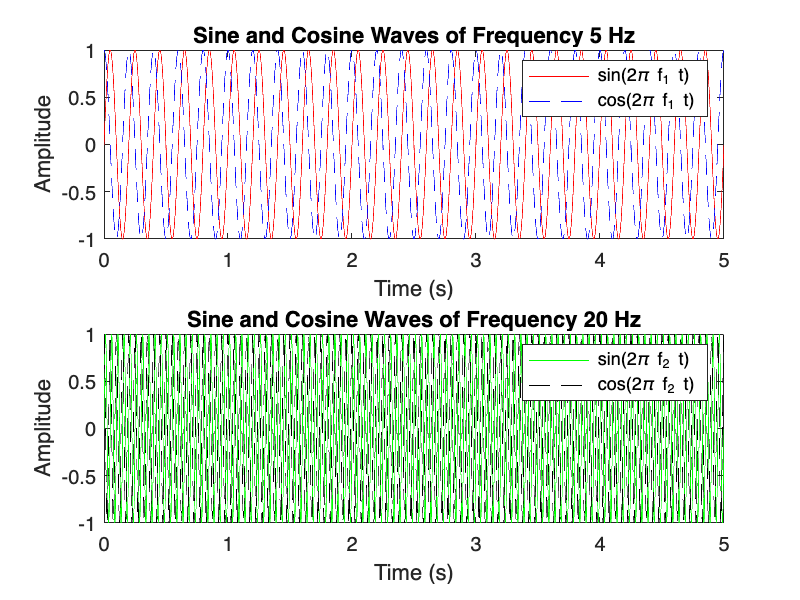

% Frequencies for the sinusoids
f1 = 5; % Frequency of the first sinusoid in Hz
f2 = 20; % Frequency of the second sinusoid in Hz

% Time vector
t = 0:1/Fs:T-1/Fs; 

% Generate the sinusoids
y1_sin = sin(2*pi*f1*t); % Sine wave of frequency f1
y1_cos = cos(2*pi*f1*t); % Cosine wave of frequency f1
y2_sin = sin(2*pi*f2*t); % Sine wave of frequency f2
y2_cos = cos(2*pi*f2*t); % Cosine wave of frequency f2

% Plot the sinusoids
figure;
subplot(2,1,1); % Subplot for the first set of frequencies
plot(t, y1_sin, 'r', t, y1_cos, 'b--');
title(['Sine and Cosine Waves of Frequency ' num2str(f1) ' Hz']);
xlabel('Time (s)');
ylabel('Amplitude');
legend('sin(2\pi f_1 t)', 'cos(2\pi f_1 t)');

subplot(2,1,2); % Subplot for the second set of frequencies
plot(t, y2_sin, 'g', t, y2_cos, 'k--');
title(['Sine and Cosine Waves of Frequency ' num2str(f2) ' Hz']);
xlabel('Time (s)');
ylabel('Amplitude');
legend('sin(2\pi f_2 t)', 'cos(2\pi f_2 t)');

### **Finding and Plotting the Discrete Fourier Transform (DFT) of the signal of the recorded audio signal.**

Using the fft function we can can convert our signal to a frequency domain signal.

% Calculate the DFT of the recorded audio signal
audioDataFFT = fft(audioData);

% Calculate the frequency vector for plotting
N = length(audioData);
freqVector = (0:N-1)*Fs/N;

% Plot the magnitude spectrum of the DFT
figure;
plot(freqVector, abs(audioDataFFT));
title('Magnitude Spectrum of the Recorded Audio Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

### **Calculating the spectral density of the signal **

We will use the Pwelch function for this the pwelch function take several parameters of the signal and calculates the Power Spectral Density (PSD).

By plotting the PSD, you can visualize the distribution of power across different frequencies in the recorded audio signal. This can be useful for analyzing the frequency content of the signal, identifying dominant frequency components, and potentially detecting any unwanted noise or interference.

% Calculate the power spectral density (PSD) using Welch's method
[psd, freqVector] = pwelch(audioData, [], [], [], Fs);

% Plot the PSD
figure;
plot(freqVector, 10*log10(psd));
title('Power Spectral Density of the Recorded Audio Signal');
xlabel('Frequency (Hz)');
ylabel('Power Spectral Density (dB/Hz)');

### **Visualization of Aliasing **

We need to generate high sampling frequency in Hz to generate a "continuous" signal and high frequency of the sinussoid in Hz.

% Parameters for the original high-frequency sinusoid
Fs_high = 10000; % High sampling frequency in Hz to generate a "continuous" signal
f_high = 1500; % High frequency of the sinusoid in Hz
T = 0.02; % Duration of the signals in seconds

**Passing signal through ideal lowpass signal **

% Parameters for the low-pass filter
cutoffFrequency = 10; % Cutoff frequency in Hz
filterOrder = 6; % Order of the filter

% Design the low-pass filter
lpFilter = designfilt('lowpassfir', 'FilterOrder', filterOrder, ...
    'CutoffFrequency', cutoffFrequency, 'SampleRate', Fs);

% Combine the signals for demonstration
combinedSignal = y1_sin + y2_sin; % Example combination of the two sine waves

% Apply the low-pass filter to the combined signal
filteredSignal = filter(lpFilt, combinedSignal);

% Plot the original and filtered signals
figure;
subplot(2,1,1);
plot(t, combinedSignal);
title('Original Combined Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2,1,2);
plot(t, filteredSignal);
title('Filtered Signal (Low-Pass Filter Applied)');
xlabel('Time (s)');
ylabel('Amplitude');